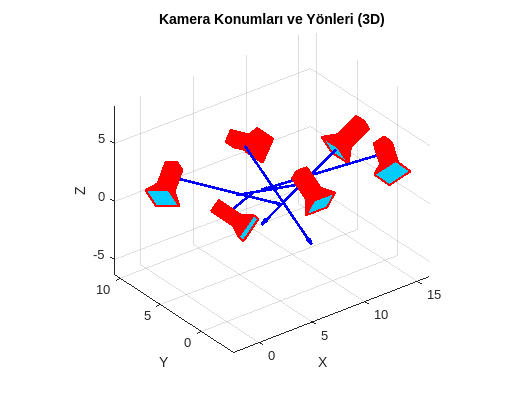

load('cam_all_params.mat');
ProjectionMatrix;

tic;


I0 = imread('cam0.png');
I1 = imread('cam1.png');

I0 = undistortImage(I0, cameraParams_0);
I1 = undistortImage(I1, cameraParams_1);

[BW0, maskedRGBImage0] = createMask(I0);
[BW1, maskedRGBImage1] = createMask(I1);

[labeledImage0, numObjects0] = bwlabel(BW0);
[labeledImage1, numObjects1] = bwlabel(BW1);

stats0 = regionprops(labeledImage0, 'Centroid', 'BoundingBox', 'Area');
stats1 = regionprops(labeledImage1, 'Centroid', 'BoundingBox', 'Area');
point3d = zeros(length(stats0), 3);

for k = 1:length(stats0)
    point3d(k, :) = triangulate(stats0(k).Centroid, stats1(k).Centroid, P{1}, P{2});
end
%point3d = triangulate(stats0.Centroid, stats1.Centroid, stereo01Params);
distanceInMeters = norm(point3d)/100;


distanceAsString = sprintf('%0.3f meters', distanceInMeters);
label = sprintf('X: %.2f, Y: %.2f, Z: %.2f', point3d(k,1), point3d(k,2), point3d(k,3));

for k = 1:length(stats0)
    boundingBox0 = stats0(k).BoundingBox;
    boundingBox1 = stats1(k).BoundingBox;

    I0 = insertObjectAnnotation(I0, 'rectangle', boundingBox0, label, 'FontSize', 30);
    I1 = insertObjectAnnotation(I1, 'rectangle', boundingBox1, label, 'FontSize', 30);

    I0 = insertShape(I0, 'rectangle', boundingBox0);
    I1 = insertShape(I1, 'rectangle', boundingBox1);
end

'catalogue:/etc/X11/fontpath.d/../truetype/' not found. Check the path or file permissions.
'catalogue:/etc/X11/fontpath.d/../TrueType/' not found. Check the path or file permissions.
'catalogue:/etc/X11/fontpath.d/../TTF/' not found. Check the path or file permissions.
'catalogue:/etc/X11/fontpath.d/../truetype/' not found. Check the path or file permissions.
'catalogue:/etc/X11/fontpath.d/../TrueType/' not found. Check the path or file permissions.
'catalogue:/etc/X11/fontpath.d/../TTF/' not found. Check the path or file permissions.


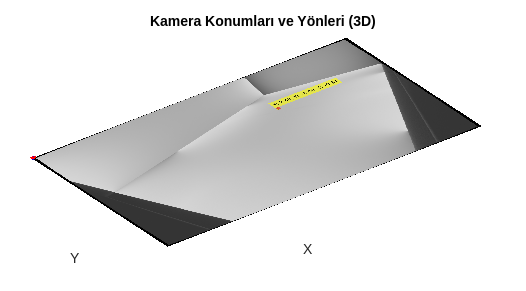


%I0 = insertObjectAnnotation(I0, 'rectangle', stats0, distanceAsString, 'FontSize', 18);
%I1 = insertObjectAnnotation(I1, 'rectangle', stats1, distanceAsString, 'FontSize', 18);
%I0 = insertShape(I0, 'filled-rectangle', stats0);
%I1 = insertShape(I1, 'filled-rectangle', stats1);

imshow(I0)

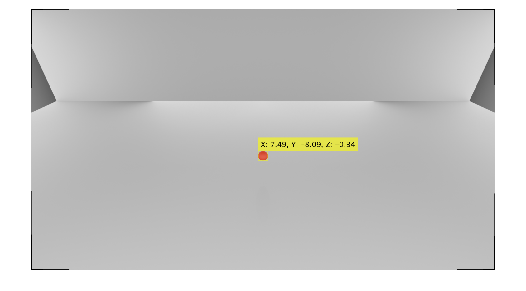

imshow(I1)

imwrite(I0, 'I0.png');
imwrite(I1, 'I1.png');
toc

Elapsed time is 33.575367 seconds.


% real poind3d = [7.5, 4, 0.1
point3d

point3d =     7.4921   -8.0882   -0.3429
